## **Internal Cross Validation of Multiple Linear Regression Model - Main Sample (HCP) **

## **Part 1: Internal Cross Validation of Multiple Linear Regression Model  **

This  is Part 1 of the Internal Cross Validation of the Multiple Linear Regression Model. It partitions the sample into 5 different folds and creates the positive and negative NMAs for each training fold and test fold based on the correllation with cognitive ability scores. 

Before Running this script:

- all scripts in HCP Data Prep 

- run HCP_compute_coupling_measures

**1) Create a cell that contains for each subject a vector of 8 predictors for each node **

for i = 1:1030
    x = final_r_all_HCP_1030_new{i,1};
    for j = 1:358
    Node_all_baseline_best_measures_HCP_weighted_only{i,j} = x(j,:);
    end
end


**2) Create cell that contains information from all subjects and all coupling measures for all nodes separetely (1030*8)**

% extract for each collumn 8 rows from each row and put them together in a matrix (--> I need 1030*16 Matrix for each Node)

n = size(Node_all_baseline_best_measures_HCP_weighted_only,2);
All_Nodes_complete_baseline_best_measures_HCP_weighted_only = cell(1,n);
for j = 1:n
    All_Nodes_complete_baseline_best_measures_HCP_weighted_only{j} = vertcat(Node_all_baseline_best_measures_HCP_weighted_only{:,j});
end 

**3) Split into 5 folds **

**Create a Loop to Do the Partition 100 times **

for cross_validation_round = 1:100;
    display(cross_validation_round)

cross_validation_round = 1

cross_validation_round = 2

cross_validation_round = 3

cross_validation_round = 4

cross_validation_round = 5

cross_validation_round = 6

cross_validation_round = 7

cross_validation_round = 8

cross_validation_round = 9

cross_validation_round = 10

cross_validation_round = 11

cross_validation_round = 12

cross_validation_round = 13

cross_validation_round = 14

cross_validation_round = 15

cross_validation_round = 16

cross_validation_round = 17

cross_validation_round = 18

cross_validation_round = 19

cross_validation_round = 20

cross_validation_round = 21

cross_validation_round = 22

cross_validation_round = 23

cross_validation_round = 24

cross_validation_round = 25

cross_validation_round = 26

cross_validation_round = 27

cross_validation_round = 28

cross_validation_round = 29

cross_validation_round = 30

cross_validation_round = 31

cross_validation_round = 32

cross_validation_round = 33

cross_validation_round = 34

cross_validation_round = 35

cross_validation_round = 36

cross_validation_round = 37

cross_validation_round = 38

cross_validation_round = 39

cross_validation_round = 40

cross_validation_round = 41

cross_validation_round = 42

cross_validation_round = 43

cross_validation_round = 44

cross_validation_round = 45

cross_validation_round = 46

cross_validation_round = 47

cross_validation_round = 48

cross_validation_round = 49

cross_validation_round = 50

cross_validation_round = 51

cross_validation_round = 52

cross_validation_round = 53

cross_validation_round = 54

cross_validation_round = 55

cross_validation_round = 56

cross_validation_round = 57

cross_validation_round = 58

cross_validation_round = 59

cross_validation_round = 60

cross_validation_round = 61

cross_validation_round = 62

cross_validation_round = 63

cross_validation_round = 64

cross_validation_round = 65

cross_validation_round = 66

cross_validation_round = 67

cross_validation_round = 68

cross_validation_round = 69

cross_validation_round = 70

cross_validation_round = 71

cross_validation_round = 72

cross_validation_round = 73

cross_validation_round = 74

cross_validation_round = 75

cross_validation_round = 76

cross_validation_round = 77

cross_validation_round = 78

cross_validation_round = 79

cross_validation_round = 80

cross_validation_round = 81

cross_validation_round = 82

cross_validation_round = 83

cross_validation_round = 84

cross_validation_round = 85

cross_validation_round = 86

cross_validation_round = 87

cross_validation_round = 88

cross_validation_round = 89

cross_validation_round = 90

cross_validation_round = 91

cross_validation_round = 92

cross_validation_round = 93

cross_validation_round = 94

cross_validation_round = 95

cross_validation_round = 96

cross_validation_round = 97

cross_validation_round = 98

cross_validation_round = 99

cross_validation_round = 100

## **Create Cross-Validation Partition based on Family IQ**

This part of the script creates a partition for the internal cross validation of the linear regression model that is stratified based on Family IQ. That way, we respect the family structures in the HCP and create a distribution of subjects in the test and training samples that is not biased towards cognitive ability scores. 

3.1) Assign the variables

HCP_family_ID = HCP_behavioral_1030.Family_ID;
HCP_Subject_names = HCP_behavioral_1030.Subject_ID;
HCP_g_score = HCP_behavioral_1030.G_Factor;

3.2) Create a table containing all the information that I need 

[number_of_families,~,family_group_number] = unique(HCP_behavioral_1030.Family_ID); % tells me which subject belongs to which family --> Indices  


for i = 1:431 % because there is 431 familys in the sample (unique output 1) 
    
    indices_for_same_family = find(family_group_number == i);
    subject_ID_same_fam = HCP_Subject_names(indices_for_same_family);
    family_ID_original = HCP_family_ID(indices_for_same_family);
    g_score_same_fam = HCP_g_score(indices_for_same_family);
    
    family_info_HCP{i,1} = i;
    family_info_HCP{i,2} = family_ID_original;
    family_info_HCP{i,3} = indices_for_same_family;
    family_info_HCP{i,4} = subject_ID_same_fam;
    family_info_HCP{i,5} = g_score_same_fam;
    
end

3.3) Create a Family IQ

for i = 1:431
    family_IQ_separate = family_info_HCP{i,5};
    family_IQ_average = mean(family_IQ_separate);
    family_info_HCP{i,6} = family_IQ_average;
end

3.4) Convert cell to table

family_info_HCP_table = cell2table(family_info_HCP);
family_info_HCP_table.Properties.VariableNames = {'Group Number','Original_Family_ID', 'Indices_for_same_Family', 'Subject_ID_same_fam', 'g_score_separate_same_fam', 'Mean_g_score_same_fam'};

3.5) Create a CV partition based on Family IQ (for the families) 

Intelligence = family_info_HCP_table.Mean_g_score_same_fam;


Intelligence_for_cv_partition_1 = rescale(Intelligence,1,30);
Intelligence_for_cv_partition = int16(Intelligence_for_cv_partition_1); % create 30 groups to ultimatly create a stratified cv partition


c = cvpartition(Intelligence_for_cv_partition,'KFold',5);

3.6) Create output: indices for the families

% Train 1 & Test 1 

index_test_1 = find(test(c,1));
index_train_1 = find(training(c,1));

% Train 2 & Test 2 
index_test_2 = find(test(c,2));
index_train_2 = find(training(c,2));

% Train 3 & Test 3 

index_test_3 = find(test(c,3));
index_train_3 = find(training(c,3));

% Train 4 & Test 4 

index_test_4 = find(test(c,4));
index_train_4 = find(training(c,4));

% Train 5 & Test 5 

index_test_5 = find(test(c,5));
index_train_5 = find(training(c,5));


3.7) Reassign the individual subjects back into the groups from the partition 

% Train 1 & Test 1 

test_1 = family_info_HCP_table.Indices_for_same_Family(index_test_1);
index_test_1_fam = cat(1,test_1{:,1});
index_test_1_fam = sort(index_test_1_fam,"ascend");

train_1 = family_info_HCP_table.Indices_for_same_Family(index_train_1);
index_train_1_fam = cat(1,train_1{:,1});
index_train_1_fam = sort(index_train_1_fam,"ascend");

% Train 2 & Test 2 

test_2 = family_info_HCP_table.Indices_for_same_Family(index_test_2);
index_test_2_fam = cat(1,test_2{:,1});
index_test_2_fam = sort(index_test_2_fam,"ascend");

train_2 = family_info_HCP_table.Indices_for_same_Family(index_train_2);
index_train_2_fam = cat(1,train_2{:,1});
index_train_2_fam = sort(index_train_2_fam,"ascend");


% Train 3 & Test 3 

test_3 = family_info_HCP_table.Indices_for_same_Family(index_test_3);
index_test_3_fam = cat(1,test_3{:,1});
index_test_3_fam = sort(index_test_3_fam,"ascend");

train_3 = family_info_HCP_table.Indices_for_same_Family(index_train_3);
index_train_3_fam = cat(1,train_3{:,1});
index_train_3_fam = sort(index_train_3_fam,"ascend");


% Train 4 & Test 4 

test_4 = family_info_HCP_table.Indices_for_same_Family(index_test_4);
index_test_4_fam = cat(1,test_4{:,1});
index_test_4_fam = sort(index_test_4_fam,"ascend");

train_4 = family_info_HCP_table.Indices_for_same_Family(index_train_4);
index_train_4_fam = cat(1,train_4{:,1});
index_train_4_fam = sort(index_train_4_fam,"ascend");


% Train 5 & Test 5 

test_5 = family_info_HCP_table.Indices_for_same_Family(index_test_5);
index_test_5_fam = cat(1,test_5{:,1});
index_test_5_fam = sort(index_test_5_fam,"ascend");

train_5 = family_info_HCP_table.Indices_for_same_Family(index_train_5);
index_train_5_fam = cat(1,train_5{:,1});
index_train_5_fam = sort(index_train_5_fam,"ascend");

% done with creating the training/test partition

**4) Divide Data in Test and Training Samples **

4.1.)  Divide the coupling data into 5 training and 5 test samples

for i = 1:358
   all_data_node = All_Nodes_complete_baseline_best_measures_HCP_weighted_only{1,i};
   
   Node_training_sample_1 = all_data_node(index_train_1_fam,:);
   Node_test_sample_1 = all_data_node(index_test_1_fam,:);
   
   Node_training_sample_2 = all_data_node(index_train_2_fam,:);
   Node_test_sample_2 = all_data_node(index_test_2_fam,:);
   
   Node_training_sample_3 = all_data_node(index_train_3_fam,:);
   Node_test_sample_3 = all_data_node(index_test_3_fam, :);
   
   Node_training_sample_4 = all_data_node(index_train_4_fam,:);
   Node_test_sample_4 = all_data_node(index_test_4_fam,:);
   
   Node_training_sample_5 = all_data_node(index_train_5_fam,:);
   Node_test_sample_5 = all_data_node(index_test_5_fam, :);
   
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{1,i} = Node_training_sample_1;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{2,i} = Node_training_sample_2;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{3,i} = Node_training_sample_3;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{4,i} = Node_training_sample_4;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{5,i} = Node_training_sample_5;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{6,i} = Node_test_sample_1;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{7,i} = Node_test_sample_2;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{8,i} = Node_test_sample_3;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{9,i} = Node_test_sample_4;
   All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{10,i} = Node_test_sample_5;
   
end

4.2) Divide Intelligence into 5 Training Samples & 5 Test Samples

Intelligence = HCP_behavioral_1030.G_Factor;

Intelligence_train_1 = Intelligence(index_train_1_fam,:);
Intelligence_train_2 = Intelligence(index_train_2_fam,:);
Intelligence_train_3 = Intelligence(index_train_3_fam,:);
Intelligence_train_4 = Intelligence(index_train_4_fam,:);
Intelligence_train_5 = Intelligence(index_train_5_fam,:);

Intelligence_test_1 = Intelligence(index_test_1_fam,:);
Intelligence_test_2 = Intelligence(index_test_2_fam,:);
Intelligence_test_3 = Intelligence(index_test_3_fam,:);
Intelligence_test_4 = Intelligence(index_test_4_fam,:);
Intelligence_test_5 = Intelligence(index_test_5_fam,:);

Intelligence_training_samples{1,:} = Intelligence_train_1;
Intelligence_training_samples{2,:} = Intelligence_train_2;
Intelligence_training_samples{3,:} = Intelligence_train_3;
Intelligence_training_samples{4,:} = Intelligence_train_4;
Intelligence_training_samples{5,:} = Intelligence_train_5;

Intelligence_test_samples{1,:} = Intelligence_test_1;
Intelligence_test_samples{2,:} = Intelligence_test_2;
Intelligence_test_samples{3,:} = Intelligence_test_3;
Intelligence_test_samples{4,:} = Intelligence_test_4;
Intelligence_test_samples{5,:} = Intelligence_test_5;

4.3)  Divide Confounding Variables into 5 Training Samples & 5 Test Samples

ALter = HCP_behavioral_1030.Age;

ALter_train_1 = ALter(index_train_1_fam,:);
ALter_train_2 = ALter(index_train_2_fam,:);
ALter_train_3 = ALter(index_train_3_fam,:);
ALter_train_4 = ALter(index_train_4_fam,:);
ALter_train_5 = ALter(index_train_5_fam,:);

ALter_test_1 = ALter(index_test_1_fam,:);
ALter_test_2 = ALter(index_test_2_fam,:);
ALter_test_3 = ALter(index_test_3_fam,:);
ALter_test_4 = ALter(index_test_4_fam,:);
ALter_test_5 = ALter(index_test_5_fam, :);


ALter_training_samples{1,:} = ALter_train_1;
ALter_training_samples{2,:} = ALter_train_2;
ALter_training_samples{3,:} = ALter_train_3;
ALter_training_samples{4,:} = ALter_train_4;
ALter_training_samples{5,:} = ALter_train_5;

ALter_test_samples{1,:} = ALter_test_1;
ALter_test_samples{2,:} = ALter_test_2;
ALter_test_samples{3,:} = ALter_test_3;
ALter_test_samples{4,:} = ALter_test_4;
ALter_test_samples{5,:} = ALter_test_5;

Gender = HCP_behavioral_1030.("Gender num");

Gender_train_1 = Gender(index_train_1_fam,:);
Gender_train_2 = Gender(index_train_2_fam,:);
Gender_train_3 = Gender(index_train_3_fam,:);
Gender_train_4 = Gender(index_train_4_fam,:);
Gender_train_5 = Gender(index_train_5_fam,:);

Gender_test_1 = Gender(index_test_1_fam,:);
Gender_test_2 = Gender(index_test_2_fam,:);
Gender_test_3 = Gender(index_test_3_fam,:);
Gender_test_4 = Gender(index_test_4_fam,:);
Gender_test_5 = Gender(index_test_5_fam,:);

Gender_training_samples{1,:} = Gender_train_1;
Gender_training_samples{2,:} = Gender_train_2;
Gender_training_samples{3,:} = Gender_train_3;
Gender_training_samples{4,:} = Gender_train_4;
Gender_training_samples{5,:} = Gender_train_5;

Gender_test_samples{1,:} = Gender_test_1;
Gender_test_samples{2,:} = Gender_test_2;
Gender_test_samples{3,:} = Gender_test_3;
Gender_test_samples{4,:} = Gender_test_4;
Gender_test_samples{5,:} = Gender_test_5;

meanFDJenk = HCP_behavioral_1030.Mean_mean_FD;

meanFDJenk_train_1 = meanFDJenk(index_train_1_fam,:);
meanFDJenk_train_2 = meanFDJenk(index_train_2_fam,:);
meanFDJenk_train_3 = meanFDJenk(index_train_3_fam,:);
meanFDJenk_train_4 = meanFDJenk(index_train_4_fam,:);
meanFDJenk_train_5 = meanFDJenk(index_train_5_fam,:);

meanFDJenk_test_1 = meanFDJenk(index_test_1_fam,:);
meanFDJenk_test_2 = meanFDJenk(index_test_2_fam,:);
meanFDJenk_test_3 = meanFDJenk(index_test_3_fam, :);
meanFDJenk_test_4 = meanFDJenk(index_test_4_fam,:);
meanFDJenk_test_5 = meanFDJenk(index_test_5_fam, :);


meanFDJenk_training_samples{1,:} = meanFDJenk_train_1;
meanFDJenk_training_samples{2,:} = meanFDJenk_train_2;
meanFDJenk_training_samples{3,:} = meanFDJenk_train_3;
meanFDJenk_training_samples{4,:} = meanFDJenk_train_4;
meanFDJenk_training_samples{5,:} = meanFDJenk_train_5;

meanFDJenk_test_samples{1,:} = meanFDJenk_test_1;
meanFDJenk_test_samples{2,:} = meanFDJenk_test_2;
meanFDJenk_test_samples{3,:} = meanFDJenk_test_3;
meanFDJenk_test_samples{4,:} = meanFDJenk_test_4;
meanFDJenk_test_samples{5,:} = meanFDJenk_test_5;

LQ = HCP_behavioral_1030.Handedness;

LQ_train_1 = LQ(index_train_1_fam,:);
LQ_train_2 = LQ(index_train_2_fam,:);
LQ_train_3 = LQ(index_train_3_fam,:);
LQ_train_4 = LQ(index_train_4_fam,:);
LQ_train_5 = LQ(index_train_5_fam,:);

LQ_test_1 = LQ(index_test_1_fam,:);
LQ_test_2 = LQ(index_test_2_fam,:);
LQ_test_3 = LQ(index_test_3_fam,:);
LQ_test_4 = LQ(index_test_4_fam,:);
LQ_test_5 = LQ(index_test_5_fam,:);


LQ_training_samples{1,:} = LQ_train_1;
LQ_training_samples{2,:} = LQ_train_2;
LQ_training_samples{3,:} = LQ_train_3;
LQ_training_samples{4,:} = LQ_train_4;
LQ_training_samples{5,:} = LQ_train_5;

LQ_test_samples{1,:} = LQ_test_1;
LQ_test_samples{2,:} = LQ_test_2;
LQ_test_samples{3,:} = LQ_test_3;
LQ_test_samples{4,:} = LQ_test_4;
LQ_test_samples{5,:} = LQ_test_5;

**5) Build a positive and negative Node Measure Assignment (NMA) for each Training Fold**

5.1) Build a correlation matrix for each training fold 


for fold = 1:5
    
Correlation_com_measures_fold_rho = zeros(358,8); % Preallocation
Correlation_com_measure_fold_pval = zeros(358,8); % Preallocation
    
for i = 1:358 % mache das für jede Node Extra
    All_Communication_measures_per_node = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{fold,i};
    
     for p = 1:8 % jetzt jedes communication measure mit Intelligenz korrelieren
        Communication_Measure_separate = All_Communication_measures_per_node(:,p);
        
             % Correlation

                x = [Communication_Measure_separate, Intelligence_training_samples{fold}];
                z = [ALter_training_samples{fold}, Gender_training_samples{fold}, meanFDJenk_training_samples{fold}, LQ_training_samples{fold}]; % control variables
   
                [rho,pval] = partialcorr(x,z);
                
                rho = rho(1,2);
                pval = pval(1,2);
            
               Correlation_com_measures_fold_rho(i,p) = rho;
               Correlation_com_measure_fold_pval(i,p) = pval;

               
    end
end

Correlation_matrices_all_folds{fold,1} = Correlation_com_measures_fold_rho;
Correlation_matrices_all_folds{fold,2} = Correlation_com_measure_fold_pval;
end

5.2) Build positive and negative NMA for each training sample 

5.2.1) Find out which ones correlate the most positive with intelligence 

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};
for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Max_Rho = max(Correlation_rho_per_node);
    Idx_max_rho = find(Correlation_rho_per_node == Max_Rho);
    Info_best_performing_communication_measure_pos_train_rho{i,1} = Max_Rho;
    Info_best_performing_communication_measure_pos_train_idx{i,1} = Idx_max_rho;
end
Pos_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_pos_train_rho;
Pos_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_pos_train_idx;
end

5.2.2) Find out which ones correlate the most negative with intelligence

for fold = 1:5
    Correlation_com_measures_fold_rho = Correlation_matrices_all_folds{fold,1};

for i = 1:358
    Correlation_rho_per_node = Correlation_com_measures_fold_rho(i,:);
    Min_Rho = min(Correlation_rho_per_node);
    Idx_min_rho = find(Correlation_rho_per_node == Min_Rho);
    Info_best_performing_communication_measure_neg_train_rho{i,1} = Min_Rho;
    Info_best_performing_communication_measure_neg_train_idx{i,1} = Idx_min_rho;
end
Neg_NMA_all_fold{fold,1} = Info_best_performing_communication_measure_neg_train_rho;
Neg_NMA_all_fold{fold,2} = Info_best_performing_communication_measure_neg_train_idx;
end

5.3) Define Sizes of Training Samples and Test Samples 

size_training_sample_1 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{1,1},1);
size_training_sample_2 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{2,1},1);
size_training_sample_3 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{3,1},1);
size_training_sample_4 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{4,1},1);
size_training_sample_5 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{5,1},1);

size_test_sample_1 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{6,1},1);
size_test_sample_2 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{7,1},1);
size_test_sample_3 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{8,1},1);
size_test_sample_4 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{9,1},1);
size_test_sample_5 = size(All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{10,1},1);

size_training_test_samples{1,1} = size_training_sample_1;
size_training_test_samples{2,1} = size_training_sample_2;
size_training_test_samples{3,1} = size_training_sample_3;
size_training_test_samples{4,1} = size_training_sample_4;
size_training_test_samples{5,1} = size_training_sample_5;

size_training_test_samples{1,2} = size_test_sample_1;
size_training_test_samples{2,2} = size_test_sample_2;
size_training_test_samples{3,2} = size_test_sample_3;
size_training_test_samples{4,2} = size_test_sample_4;
size_training_test_samples{5,2} = size_test_sample_5; 

5.4) Extract the NMA values for the positive NMA

for fold = 1:5

size_sample = size_training_test_samples{fold,1};     
Best_case_scenario_r_values_pos_train = zeros(358,size_sample);
best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{fold,i}(:,index); 
    Best_case_scenario_r_values_pos_train(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_train = Best_case_scenario_r_values_pos_train';

Best_case_scenario_training_samples{fold,1} = Best_case_scenario_r_values_pos_train;

end 

5.5) Extract the NMA values for the negative NMA

for fold = 1:5
   
size_sample = size_training_test_samples{fold,1};
Best_case_scenario_r_values_neg_train = zeros(358,size_sample);
best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});

for i = 1:358
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{fold,i}(:,index);
    Best_case_scenario_r_values_neg_train(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_train = Best_case_scenario_r_values_neg_train';

Best_case_scenario_training_samples{fold,2} = Best_case_scenario_r_values_neg_train;

end 

**6) Build a positive and negative Node Measure Assignment (NMA) for each Test Fold**

6.1) Extract the NMA values for the positive NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_pos_test = zeros(358,size_sample);
    best_performing_measure_per_node_pos = cell2mat(Pos_NMA_all_fold{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_pos(i);
    Best_scenario_node_values_pos = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_pos_test(i,:) = Best_scenario_node_values_pos';
end

Best_case_scenario_r_values_pos_test = Best_case_scenario_r_values_pos_test';

Best_case_scenario_test_samples{fold,1} = Best_case_scenario_r_values_pos_test;

end

6.2) Extract the NMA values for the negative NMA

for fold = 1:5
    size_sample = size_training_test_samples{fold,2};
    Best_case_scenario_r_values_neg_test = zeros(358,size_sample);
    best_performing_measure_per_node_neg = cell2mat(Neg_NMA_all_fold{fold,2});
    index_into_crossvall = fold+5;

for i = 1:358 
    index = best_performing_measure_per_node_neg(i);
    Best_scenario_node_values_neg = All_Nodes_complete_cross_validation_HCP_baseline_weighted_only{index_into_crossvall,i}(:,index);
    Best_case_scenario_r_values_neg_test(i,:) = Best_scenario_node_values_neg';
end

Best_case_scenario_r_values_neg_test = Best_case_scenario_r_values_neg_test';

Best_case_scenario_test_samples{fold,2} = Best_case_scenario_r_values_neg_test;

end



## **Part 2: Internal Cross Validation of Multiple Linear Regression**

This  is Part 2 of the Cross Validation of the Multiple Linear Regression Model. It uses the Node-Measure Assignments that were created above 

to build multiple linear regression models that are then tested in the test sample. 

**1) Build the Models for the Training Samples **

Training Sample 1

Convert scores into z-scores

Alter_train_1_z = normalize(ALter_train_1);
Gender_train_1_z = normalize(Gender_train_1);
meanFDJenk_train_1_z = normalize(meanFDJenk_train_1);
LQ_train_1_z = normalize(LQ_train_1);

Intelligence_train_1_z = normalize(Intelligence_train_1);


Regress out the confounding variables from intelligence

confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z];

mdl_regress_train_1_intelligence = fitlm(confounds,Intelligence_train_1_z);
residuals_intelligence_train_1_z = mdl_regress_train_1_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

Build the actual model

Model_Matrix = [residuals_pos_train_1 residuals_neg_train_1 residuals_intelligence_train_1_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1', 'residuals_neg_train_1','Residuals_intelligence_train_1_z'};

mdl_pos_neg_bcs_train_1 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1);


**Training Sample 2**

Convert scores into z-scores

ALter_train_2_z = normalize(ALter_train_2);
Gender_train_2_z = normalize(Gender_train_2);
meanFDJenk_train_2_z = normalize(meanFDJenk_train_2);
LQ_train_2_z = normalize(LQ_train_2);

Intelligence_train_2_z = normalize(Intelligence_train_2);

Regress out the confounding variables from intelligence

confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z];

mdl_regress_train_2_intelligence = fitlm(confounds,Intelligence_train_2_z);
residuals_intelligence_train_2_z = mdl_regress_train_2_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);


Regress out the confounding Variables from positive and negative NMA

confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

Build the actual model

Model_Matrix = [residuals_pos_train_2 residuals_neg_train_2 residuals_intelligence_train_2_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2','residuals_neg_train_1','Residuals_intelligence_train_2_z'};

mdl_pos_neg_bcs_train_2 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2);

**Training Sample 3**

Convert scores into z-scores

ALter_train_3_z = normalize(ALter_train_3);
Gender_train_3_z = normalize(Gender_train_3);
meanFDJenk_train_3_z = normalize(meanFDJenk_train_3);
LQ_train_3_z = normalize(LQ_train_3);

Intelligence_train_3_z = normalize(Intelligence_train_3);

Regress out the confounding variables from intelligence

confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z];

mdl_regress_train_3_intelligence = fitlm(confounds,Intelligence_train_3_z);
residuals_intelligence_train_3_z = mdl_regress_train_3_intelligence.Residuals.Raw;

Retrieve NMA for the subjects 

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA 

confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

Build the actual model

Model_Matrix = [residuals_pos_train_3 residuals_neg_train_3 residuals_intelligence_train_3_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3', 'residuals_neg_train_3','Residuals_intelligence_train_3_z'};

mdl_pos_neg_bcs_train_3 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3);


**Training Sample 4**

Convert scores into z-scores

ALter_train_4_z = normalize(ALter_train_4);
Gender_train_4_z = normalize(Gender_train_4);
meanFDJenk_train_4_z = normalize(meanFDJenk_train_4);
LQ_train_4_z = normalize(LQ_train_4);

Intelligence_train_4_z = normalize(Intelligence_train_4);

Regress out the confounding Variables from intelligence

confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z];

mdl_regress_train_4_intelligence = fitlm(confounds,Intelligence_train_4_z);
residuals_intelligence_train_4_z = mdl_regress_train_4_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

Build the actual model

Model_Matrix = [residuals_pos_train_4 residuals_neg_train_4 residuals_intelligence_train_4_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4', 'residuals_neg_train_4','Residuals_intelligence_train_4_z'};

mdl_pos_neg_bcs_train_4 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4);


**Training Sample 5**

Convert scores into z-scores

ALter_train_5_z = normalize(ALter_train_5);
Gender_train_5_z = normalize(Gender_train_5);
meanFDJenk_train_5_z = normalize(meanFDJenk_train_5);
LQ_train_5_z = normalize(LQ_train_5);

Intelligence_train_5_z = normalize(Intelligence_train_5);

Regress out the confounding variables from intelligence

confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z];

mdl_regress_train_5_intelligence = fitlm(confounds,Intelligence_train_5_z);
residuals_intelligence_train_5_z = mdl_regress_train_5_intelligence.Residuals.Raw;

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the mean per subject and normalize 

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables from positive and negative NMA

confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

Build the actual model

Model_Matrix = [residuals_pos_train_5 residuals_neg_train_5 residuals_intelligence_train_5_z];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5', 'residuals_neg_train_5','Residuals_intelligence_train_5_z'};

mdl_pos_neg_bcs_train_5 = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5);

**2) Predict the Intelligence in Test Samples**

**Test Sample 1 **

Convert scores into z-scores

ALter_test_1_z = normalize(ALter_test_1);
Gender_test_1_z = normalize(Gender_test_1);
meanFDJenk_test_1_z = normalize(meanFDJenk_test_1);
LQ_test_1_z = normalize(LQ_test_1);

Intelligence_test_1_z = normalize(Intelligence_test_1);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z];
int_pred_test_1 = predict(mdl_regress_train_1_intelligence,confounds);

residuals_intelligence_test_1_z = (Intelligence_test_1_z - int_pred_test_1 );


Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables 

confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);

Xnew = [residuals_pos_test_1 residuals_neg_test_1];
ypred1_whole_sample = predict(mdl_pos_neg_bcs_train_1,Xnew);

[r,pval] = corr(ypred1_whole_sample,residuals_intelligence_test_1_z);

**Test Sample 2 **

Convert scores into z-scores

ALter_test_2_z = normalize(ALter_test_2);
Gender_test_2_z = normalize(Gender_test_2);
meanFDJenk_test_2_z = normalize(meanFDJenk_test_2);
LQ_test_2_z = normalize(LQ_test_2);

Intelligence_test_2_z = normalize(Intelligence_test_2);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z];
int_pred_test_2 = predict(mdl_regress_train_2_intelligence,confounds);

residuals_intelligence_test_2_z = (Intelligence_test_2_z - int_pred_test_2);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables 

confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);

Xnew = [residuals_pos_test_2 residuals_neg_test_2];
ypred2_whole_sample = predict(mdl_pos_neg_bcs_train_2,Xnew);

[r,pval] = corr(ypred2_whole_sample,residuals_intelligence_test_2_z);

**Test Sample 3** 

Convert scores into z-scores

ALter_test_3_z = normalize(ALter_test_3);
Gender_test_3_z = normalize(Gender_test_3);
meanFDJenk_test_3_z = normalize(meanFDJenk_test_3);
LQ_test_3_z = normalize(LQ_test_3);

Intelligence_test_3_z = normalize(Intelligence_test_3);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z];
int_pred_test_3 = predict(mdl_regress_train_3_intelligence,confounds);

residuals_intelligence_test_3_z = (Intelligence_test_3_z - int_pred_test_3);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);

Xnew = [residuals_pos_test_3 residuals_neg_test_3];
ypred3_whole_sample = predict(mdl_pos_neg_bcs_train_3,Xnew);


[r,pval] = corr(ypred3_whole_sample,residuals_intelligence_test_3_z);

**Test Sample 4 **

Convert scores into z-scores

ALter_test_4_z = normalize(ALter_test_4);
Gender_test_4_z = normalize(Gender_test_4);
meanFDJenk_test_4_z = normalize(meanFDJenk_test_4);
LQ_test_4_z = normalize(LQ_test_4);

Intelligence_test_4_z = normalize(Intelligence_test_4);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z];
int_pred_test_4 = predict(mdl_regress_train_4_intelligence,confounds);

residuals_intelligence_test_4_z = (Intelligence_test_4_z - int_pred_test_4);

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding variables 

confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);

Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);

Xnew = [residuals_pos_test_4 residuals_neg_test_4];
ypred4_whole_sample = predict(mdl_pos_neg_bcs_train_4,Xnew);

[r,pval] = corr(ypred4_whole_sample,residuals_intelligence_test_4_z);

**Test Sample 5 **

Convert scores into z-scores

ALter_test_5_z = normalize(ALter_test_5);
Gender_test_5_z = normalize(Gender_test_5);
meanFDJenk_test_5_z = normalize(meanFDJenk_test_5);
LQ_test_5_z = normalize(LQ_test_5);

Intelligence_test_5_z = normalize(Intelligence_test_5);


Get the raw residuals by subtracting the fitted values from the observed values (using regresion model from above)

confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z];
int_pred_test_5 = predict(mdl_regress_train_5_intelligence,confounds);

residuals_intelligence_test_5_z = (Intelligence_test_5_z - int_pred_test_5 );

Retrieve NMA for the subjects

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);

Xnew = [residuals_pos_test_5 residuals_neg_test_5];
ypred5_whole_sample = predict(mdl_pos_neg_bcs_train_5,Xnew);

[r,pval] = corr(ypred5_whole_sample,residuals_intelligence_test_5_z);

rho = 0.2515

pval = 2.5193e-16

rho = 0.2586

pval = 3.3680e-17

rho = 0.2462

pval = 1.0857e-15

rho = 0.2683

pval = 1.9179e-18

rho = 0.2482

pval = 6.2647e-16

rho = 0.2746

pval = 2.7900e-19

rho = 0.2254

pval = 2.4915e-13

rho = 0.2471

pval = 8.4715e-16

rho = 0.2659

pval = 3.9195e-18

rho = 0.2496

pval = 4.3418e-16

rho = 0.2399

pval = 5.9961e-15

rho = 0.2473

pval = 8.0342e-16

rho = 0.2218

pval = 6.0219e-13

rho = 0.2441

pval = 1.9261e-15

rho = 0.2459

pval = 1.2024e-15

rho = 0.2322

pval = 4.5286e-14

rho = 0.2608

pval = 1.7564e-17

rho = 0.2565

pval = 6.1052e-17

rho = 0.2602

pval = 2.1335e-17

rho = 0.2537

pval = 1.3742e-16

rho = 0.2606

pval = 1.9044e-17

rho = 0.2366

pval = 1.4409e-14

rho = 0.2295

pval = 8.9678e-14

rho = 0.2569

pval = 5.5079e-17

rho = 0.2673

pval = 2.5911e-18

rho = 0.2533

pval = 1.5445e-16

rho = 0.2858

pval = 8.3029e-21

rho = 0.2385

pval = 8.5702e-15

rho = 0.2431

pval = 2.5501e-15

rho = 0.2360

pval = 1.6940e-14

rho = 0.2349

pval = 2.2249e-14

rho = 0.2548

pval = 9.8833e-17

rho = 0.2610

pval = 1.6886e-17

rho = 0.2571

pval = 5.1969e-17

rho = 0.2696

pval = 1.3004e-18

rho = 0.2899

pval = 2.1790e-21

rho = 0.2579

pval = 4.1291e-17

rho = 0.2386

pval = 8.3557e-15

rho = 0.2559

pval = 7.2113e-17

rho = 0.2512

pval = 2.7265e-16

rho = 0.2527

pval = 1.8033e-16

rho = 0.2414

pval = 4.0683e-15

rho = 0.2532

pval = 1.5847e-16

rho = 0.2816

pval = 3.1476e-20

rho = 0.2614

pval = 1.5082e-17

rho = 0.2583

pval = 3.6980e-17

rho = 0.2581

pval = 3.8685e-17

rho = 0.2636

pval = 7.8488e-18

rho = 0.2634

pval = 8.2681e-18

rho = 0.2729

pval = 4.7625e-19

rho = 0.2489

pval = 5.2903e-16

rho = 0.2688

pval = 1.6557e-18

rho = 0.2636

pval = 7.7174e-18

rho = 0.2511

pval = 2.8426e-16

rho = 0.2509

pval = 3.0152e-16

rho = 0.2400

pval = 5.8787e-15

rho = 0.2724

pval = 5.5461e-19

rho = 0.2572

pval = 4.9692e-17

rho = 0.2729

pval = 4.8022e-19

rho = 0.2688

pval = 1.6755e-18

rho = 0.2505

pval = 3.3065e-16

rho = 0.2126

pval = 5.4193e-12

rho = 0.2616

pval = 1.4105e-17

rho = 0.2700

pval = 1.1409e-18

rho = 0.2415

pval = 3.8795e-15

rho = 0.2434

pval = 2.3259e-15

rho = 0.2162

pval = 2.3089e-12

rho = 0.2471

pval = 8.6595e-16

rho = 0.2304

pval = 7.1138e-14

rho = 0.2459

pval = 1.1786e-15

rho = 0.2300

pval = 7.8962e-14

rho = 0.2341

pval = 2.7380e-14

rho = 0.2579

pval = 4.1642e-17

rho = 0.2451

pval = 1.4799e-15

rho = 0.2701

pval = 1.1218e-18

rho = 0.2585

pval = 3.4339e-17

rho = 0.2113

pval = 7.3449e-12

rho = 0.2525

pval = 1.8900e-16

rho = 0.2602

pval = 2.0928e-17

rho = 0.2680

pval = 2.1398e-18

rho = 0.2691

pval = 1.4985e-18

rho = 0.2779

pval = 1.0134e-19

rho = 0.2600

pval = 2.2592e-17

rho = 0.2690

pval = 1.5430e-18

rho = 0.2486

pval = 5.6344e-16

rho = 0.2734

pval = 4.1207e-19

rho = 0.2533

pval = 1.5207e-16

rho = 0.2474

pval = 7.7922e-16

rho = 0.2538

pval = 1.3333e-16

rho = 0.2576

pval = 4.4916e-17

rho = 0.2364

pval = 1.5124e-14

rho = 0.2461

pval = 1.1167e-15

rho = 0.2528

pval = 1.7556e-16

rho = 0.2503

pval = 3.5067e-16

rho = 0.2430

pval = 2.6267e-15

rho = 0.2537

pval = 1.3726e-16

rho = 0.2329

pval = 3.6995e-14

rho = 0.2763

pval = 1.6643e-19

rho = 0.2379

pval = 1.0292e-14

rho = 0.2634

pval = 8.3321e-18

**3) Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_whole_sample; ypred2_whole_sample; ypred3_whole_sample; ypred4_whole_sample; ypred5_whole_sample];
actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

[rho,pval] = corr(predicted_scores,actual_scores)


cross_validation_100_final_correlation_HCP{cross_validation_round,1} = rho;
cross_validation_100_final_correlation_HCP{cross_validation_round,2} = pval;

## **Part 3: Permutation Test - Internal Cross Validation of Multiple Linear Regression Model **

This part tests the prediction of the internal cross-validated linear regression prediction model with a permutation test. Intelligence scores are permuted and the model predicts those permuted scores. Model performance is assessed comparing the model performance on the permuted data to model performance on the actual data. 

**1) Build the Models for the Training Samples**

Create Loop for Permutation Test 

for  permutation_test_round = 1:10
    
    display(permutation_test_round)

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

permutation_test_round = 1

permutation_test_round = 2

permutation_test_round = 3

permutation_test_round = 4

permutation_test_round = 5

permutation_test_round = 6

permutation_test_round = 7

permutation_test_round = 8

permutation_test_round = 9

permutation_test_round = 10

Training Sample 1

Convert scores into z-scores

Alter_train_1_z = normalize(ALter_train_1);
Gender_train_1_z = normalize(Gender_train_1);
meanFDJenk_train_1_z = normalize(meanFDJenk_train_1);
LQ_train_1_z = normalize(LQ_train_1);

Intelligence_train_1_z = normalize(Intelligence_train_1);
Intelligence_rand_train_1 = Intelligence_train_1_z(randperm(length(Intelligence_train_1_z)));

Regress out the confounding Variables from Intelligence

confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z];

mdl_regress_train_1_intelligence_rand = fitlm(confounds,Intelligence_rand_train_1);
residuals_intelligence_train_1_z_rand = mdl_regress_train_1_intelligence_rand.Residuals.Raw;

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{1,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA

confounds = [Alter_train_1_z Gender_train_1_z meanFDJenk_train_1_z LQ_train_1_z];

mdl_regress_train_1_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_1 = mdl_regress_train_1_pos_bcs.Residuals.Raw;

mdl_regress_train_1_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_1 = mdl_regress_train_1_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_1 residuals_neg_train_1 residuals_intelligence_train_1_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_1', 'residuals_neg_train_1','Residuals_intelligence_rand_train_1_z'};

mdl_pos_neg_bcs_train_1_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_1_rand);


Training Sample 2

Convert scores into z-scores

ALter_train_2_z = normalize(ALter_train_2);
Gender_train_2_z = normalize(Gender_train_2);
meanFDJenk_train_2_z = normalize(meanFDJenk_train_2);
LQ_train_2_z = normalize(LQ_train_2);

Intelligence_train_2_z = normalize(Intelligence_train_2);
Intelligence_rand_train_2 = Intelligence_train_2_z(randperm(length(Intelligence_train_2_z)));

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z];

mdl_regress_train_2_intelligence_rand = fitlm(confounds,Intelligence_rand_train_2);
residuals_intelligence_train_2_z_rand = mdl_regress_train_2_intelligence_rand.Residuals.Raw;

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{2,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);


Regress out the confounding Variables from positive and negative NMA

confounds = [ALter_train_2_z Gender_train_2_z meanFDJenk_train_2_z LQ_train_2_z];

mdl_regress_train_2_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_2 = mdl_regress_train_2_pos_bcs.Residuals.Raw;

mdl_regress_train_2_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_2 = mdl_regress_train_2_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_2 residuals_neg_train_2 residuals_intelligence_train_2_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_2','residuals_neg_train_1','Residuals_intelligence_rand_train_2_z'};

mdl_pos_neg_bcs_train_2_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_2_rand);

Training Sample 3

Convert scores into z-scores

ALter_train_3_z = normalize(ALter_train_3);
Gender_train_3_z = normalize(Gender_train_3);
meanFDJenk_train_3_z = normalize(meanFDJenk_train_3);
LQ_train_3_z = normalize(LQ_train_3);

Intelligence_train_3_z = normalize(Intelligence_train_3);
Intelligence_rand_train_3 = Intelligence_train_3_z(randperm(length(Intelligence_train_3_z)));

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z];

mdl_regress_train_3_intelligence_rand = fitlm(confounds,Intelligence_rand_train_3);
residuals_intelligence_train_3_z_rand = mdl_regress_train_3_intelligence_rand.Residuals.Raw;


Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{3,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA

confounds = [ALter_train_3_z Gender_train_3_z meanFDJenk_train_3_z LQ_train_3_z];

mdl_regress_train_3_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_3 = mdl_regress_train_3_pos_bcs.Residuals.Raw;

mdl_regress_train_3_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_3 = mdl_regress_train_3_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_3 residuals_neg_train_3 residuals_intelligence_train_3_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_3', 'residuals_neg_train_3','Residuals_intelligence_rand_train_3_z'};

mdl_pos_neg_bcs_train_3_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_3_rand);


Training Sample 4

Convert scores into z-scores

ALter_train_4_z = normalize(ALter_train_4);
Gender_train_4_z = normalize(Gender_train_4);
meanFDJenk_train_4_z = normalize(meanFDJenk_train_4);
LQ_train_4_z = normalize(LQ_train_4);

Intelligence_train_4_z = normalize(Intelligence_train_4);
Intelligence_rand_train_4 = Intelligence_train_4_z(randperm(length(Intelligence_train_4_z)));

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z];

mdl_regress_train_4_intelligence_rand = fitlm(confounds,Intelligence_rand_train_4);
residuals_intelligence_train_4_z_rand = mdl_regress_train_4_intelligence_rand.Residuals.Raw;

Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{4,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA

confounds = [ALter_train_4_z Gender_train_4_z meanFDJenk_train_4_z LQ_train_4_z];

mdl_regress_train_4_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_4 = mdl_regress_train_4_pos_bcs.Residuals.Raw;

mdl_regress_train_4_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_4 = mdl_regress_train_4_neg_bcs.Residuals.Raw;

Build the actual Model

Model_Matrix = [residuals_pos_train_4 residuals_neg_train_4 residuals_intelligence_train_4_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_4', 'residuals_neg_train_4','Residuals_rand_train_4_z'};

mdl_pos_neg_bcs_train_4_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_4_rand);


Training Sample 5

Convert scores into z-scores

ALter_train_5_z = normalize(ALter_train_5);
Gender_train_5_z = normalize(Gender_train_5);
meanFDJenk_train_5_z = normalize(meanFDJenk_train_5);
LQ_train_5_z = normalize(LQ_train_5);

Intelligence_train_5_z = normalize(Intelligence_train_5);
Intelligence_rand_train_5 = Intelligence_train_5_z(randperm(length(Intelligence_train_5_z)));

Regress out the confounding Variables from Intelligence

confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z];

mdl_regress_train_5_intelligence_rand = fitlm(confounds,Intelligence_rand_train_5);
residuals_intelligence_train_5_z_rand = mdl_regress_train_5_intelligence_rand.Residuals.Raw;


Retrieve the NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_training_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_training_samples{5,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables from positive and negative NMA 

confounds = [ALter_train_5_z Gender_train_5_z meanFDJenk_train_5_z LQ_train_5_z];

mdl_regress_train_5_pos_bcs = fitlm(confounds,Positive_all);
residuals_pos_train_5 = mdl_regress_train_5_pos_bcs.Residuals.Raw;

mdl_regress_train_5_neg_bcs = fitlm(confounds,Negative_all);
residuals_neg_train_5 = mdl_regress_train_5_neg_bcs.Residuals.Raw;

Build the actual Model

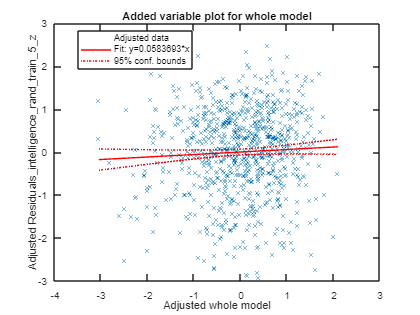

Model_Matrix = [residuals_pos_train_5 residuals_neg_train_5 residuals_intelligence_train_5_z_rand];
Model_Matrix = num2cell(Model_Matrix);
Model_Matrix_table = cell2table(Model_Matrix);
Model_Matrix_table.Properties.VariableNames = {'residuals_pos_train_5', 'residuals_neg_train_5','Residuals_intelligence_rand_train_5_z'};

mdl_pos_neg_bcs_train_5_rand = fitlm(Model_Matrix_table);
plot(mdl_pos_neg_bcs_train_5_rand);

**2) Predict the Intelligence in Test Samples **

Test Sample 1 

Convert scores into z-scores

ALter_test_1_z = normalize(ALter_test_1);
Gender_test_1_z = normalize(Gender_test_1);
meanFDJenk_test_1_z = normalize(meanFDJenk_test_1);
LQ_test_1_z = normalize(LQ_test_1);

Intelligence_test_1_z = normalize(Intelligence_test_1);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)


confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z];
int_pred_test_1 = predict(mdl_regress_train_1_intelligence_rand,confounds);

residuals_intelligence_test_1_z = (Intelligence_test_1_z - int_pred_test_1);


Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{1,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{1,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_1_z Gender_test_1_z meanFDJenk_test_1_z LQ_test_1_z];


Positive_all_pred_test_1 = predict(mdl_regress_train_1_pos_bcs,confounds);

residuals_pos_test_1 = (Positive_all - Positive_all_pred_test_1);


Negative_all_pred_test_1 = predict(mdl_regress_train_1_neg_bcs,confounds);

residuals_neg_test_1 = (Negative_all - Negative_all_pred_test_1);

Xnew = [residuals_pos_test_1 residuals_neg_test_1];
ypred1_rand = predict(mdl_pos_neg_bcs_train_1_rand,Xnew);

[r,pval] = corr(ypred1_rand,residuals_intelligence_test_1_z);

Test Sample 2 

Convert scores into z-scores

ALter_test_2_z = normalize(ALter_test_2);
Gender_test_2_z = normalize(Gender_test_2);
meanFDJenk_test_2_z = normalize(meanFDJenk_test_2);
LQ_test_2_z = normalize(LQ_test_2);

Intelligence_test_2_z = normalize(Intelligence_test_2);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z];
int_pred_test_2 = predict(mdl_regress_train_2_intelligence_rand,confounds);

residuals_intelligence_test_2_z = (Intelligence_test_2_z - int_pred_test_2);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{2,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{2,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_2_z Gender_test_2_z meanFDJenk_test_2_z LQ_test_2_z];

Positive_all_pred_test_2 = predict(mdl_regress_train_2_pos_bcs,confounds);

residuals_pos_test_2 = (Positive_all - Positive_all_pred_test_2);

Negative_all_pred_test_2 = predict(mdl_regress_train_2_neg_bcs,confounds);

residuals_neg_test_2 = (Negative_all - Negative_all_pred_test_2);

Xnew = [residuals_pos_test_2 residuals_neg_test_2];
ypred2_rand = predict(mdl_pos_neg_bcs_train_2_rand,Xnew);

[r,pval] = corr(ypred2_rand,residuals_intelligence_test_2_z);

Test Sample 3 

Convert scores into z-scores

ALter_test_3_z = normalize(ALter_test_3);
Gender_test_3_z = normalize(Gender_test_3);
meanFDJenk_test_3_z = normalize(meanFDJenk_test_3);
LQ_test_3_z = normalize(LQ_test_3);

Intelligence_test_3_z = normalize(Intelligence_test_3);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z];
int_pred_test_3 = predict(mdl_regress_train_3_intelligence_rand,confounds);

residuals_intelligence_test_3_z = (Intelligence_test_3_z - int_pred_test_3);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{3,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{3,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_3_z Gender_test_3_z meanFDJenk_test_3_z LQ_test_3_z];

Positive_all_pred_test_3 = predict(mdl_regress_train_3_pos_bcs,confounds);

residuals_pos_test_3 = (Positive_all - Positive_all_pred_test_3);

Negative_all_pred_test_3 = predict(mdl_regress_train_3_neg_bcs,confounds);

residuals_neg_test_3 = (Negative_all - Negative_all_pred_test_3);

Xnew = [residuals_pos_test_3 residuals_neg_test_3];
ypred3_rand = predict(mdl_pos_neg_bcs_train_3_rand,Xnew);


[r,pval] = corr(ypred3_rand,residuals_intelligence_test_3_z);

Test Sample 4 

Convert scores into z-scores

ALter_test_4_z = normalize(ALter_test_4);
Gender_test_4_z = normalize(Gender_test_4);
meanFDJenk_test_4_z = normalize(meanFDJenk_test_4);
LQ_test_4_z = normalize(LQ_test_4);

Intelligence_test_4_z = normalize(Intelligence_test_4);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z];
int_pred_test_4 = predict(mdl_regress_train_4_intelligence_rand,confounds);

residuals_intelligence_test_4_z = (Intelligence_test_4_z - int_pred_test_4);

Create the Averages for the People 

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{4,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{4,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_4_z Gender_test_4_z meanFDJenk_test_4_z LQ_test_4_z];

Positive_all_pred_test_4 = predict(mdl_regress_train_4_pos_bcs,confounds);

residuals_pos_test_4 = (Positive_all - Positive_all_pred_test_4);

Negative_all_pred_test_4 = predict(mdl_regress_train_4_neg_bcs,confounds);

residuals_neg_test_4 = (Negative_all - Negative_all_pred_test_4);

Xnew = [residuals_pos_test_4 residuals_neg_test_4];
ypred4_rand = predict(mdl_pos_neg_bcs_train_4_rand,Xnew);


[r,pval] = corr(ypred4_rand,residuals_intelligence_test_4_z);

Test Sample 5 

Convert scores into z-scores

ALter_test_5_z = normalize(ALter_test_5);
Gender_test_5_z = normalize(Gender_test_5);
meanFDJenk_test_5_z = normalize(meanFDJenk_test_5);
LQ_test_5_z = normalize(LQ_test_5);

Intelligence_test_5_z = normalize(Intelligence_test_5);


Get the raw residuals by subtracting the fitted values from the observed values (using regression model from above)

confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z];
int_pred_test_5 = predict(mdl_regress_train_5_intelligence_rand,confounds);

residuals_intelligence_test_5_z = (Intelligence_test_5_z - int_pred_test_5);

Retrieve NMAs

Best_case_scenario_r_values_pos = Best_case_scenario_test_samples{5,1};
Best_case_scenario_r_values_neg = Best_case_scenario_test_samples{5,2};

Take the Mean per subject

Positive_all = nanmean(Best_case_scenario_r_values_pos,2);
Negative_all = nanmean(Best_case_scenario_r_values_neg,2);

Positive_all = normalize(Positive_all);
Negative_all = normalize(Negative_all);

Regress out the confounding Variables 

confounds = [ALter_test_5_z Gender_test_5_z meanFDJenk_test_5_z LQ_test_5_z];

Positive_all_pred_test_5 = predict(mdl_regress_train_5_pos_bcs,confounds);

residuals_pos_test_5 = (Positive_all - Positive_all_pred_test_5);

Negative_all_pred_test_5 = predict(mdl_regress_train_5_neg_bcs,confounds);

residuals_neg_test_5 = (Negative_all - Negative_all_pred_test_5);

Xnew = [residuals_pos_test_5 residuals_neg_test_5];
ypred5_rand = predict(mdl_pos_neg_bcs_train_5_rand,Xnew);

[r,pval] = corr(ypred5_rand,residuals_intelligence_test_5_z);

**3)  Correlate the predicted scores with the actual scores**

predicted_scores = [ypred1_rand; ypred2_rand; ypred3_rand; ypred4_rand; ypred5_rand];
actual_scores = [residuals_intelligence_test_1_z; residuals_intelligence_test_2_z; residuals_intelligence_test_3_z; residuals_intelligence_test_4_z; residuals_intelligence_test_5_z];

[rho_final,pval_final] = corr(predicted_scores,actual_scores);

**4) Save rho_final & pval_final for Permutation Test **

Permutation_test_all_cross_val_rounds_rho{cross_validation_round,permutation_test_round} = rho_final;
Permutation_test_all_cross_val_rounds_pval{cross_validation_round, permutation_test_round} = pval_final;

**End permutation test**

end

end

## **4. Analysis Section**

all_rhos_final_correlations = cell2mat(cross_validation_100_final_correlation_HCP(:,1))

all_rhos_final_correlations =     0.2515
    0.2586
    0.2462
    0.2683
    0.2482
    0.2746
    0.2254
    0.2471
    0.2659
    0.2496



mean_all_rhos_final_correlations = mean(all_rhos_final_correlations)

mean_all_rhos_final_correlations = 0.2529


Permutation_test_all_cross_val_rounds_rho_mat = cell2mat(Permutation_test_all_cross_val_rounds_rho)

Permutation_test_all_cross_val_rounds_rho_mat =     0.0526    0.0510    0.0006   -0.0492   -0.0709    0.0303   -0.1756    0.0410   -0.0682    0.0766
   -0.0763   -0.0154   -0.0627    0.0696   -0.0351   -0.0941   -0.0838   -0.0938   -0.0344    0.1845
   -0.1396    0.1479   -0.1378    0.0606    0.0611    0.0535   -0.0480   -0.0764   -0.0988   -0.0673
    0.1057    0.1202   -0.0598   -0.0503   -0.1143   -0.0698    0.0176   -0.0485    0.0054    0.0032
    0.0104    0.0745   -0.1170    0.1360    0.0364    0.1597    0.0286    0.0404   -0.0221    0.0598
    0.0771   -0.0086    0.0482   -0.0050   -0.1052    0.0826    0.0241   -0.1101   -0.0075    0.0834
   -0.0717    0.0094   -0.0953   -0.0508   -0.0527    0.0971   -0.0442    0.0656    0.0267   -0.0414
    0.0036   -0.1321    0.0402   -0.0013    0.0760    0.1669    0.0087    0.0245   -0.0281    0.2074
   -0.0417    0.1056    0.0178   -0.1529    0.0958    0.1149    0.0231    0.0349    0.1426    0.0524
    0.0406    0.0583   -0.1107    0.1096   



find(Permutation_test_all_cross_val_rounds_rho_mat > mean_all_rhos_final_correlations)


ans =

  0×1 empty double column vector

